# Coeficientes fourier

## Ejecicio a mano

## 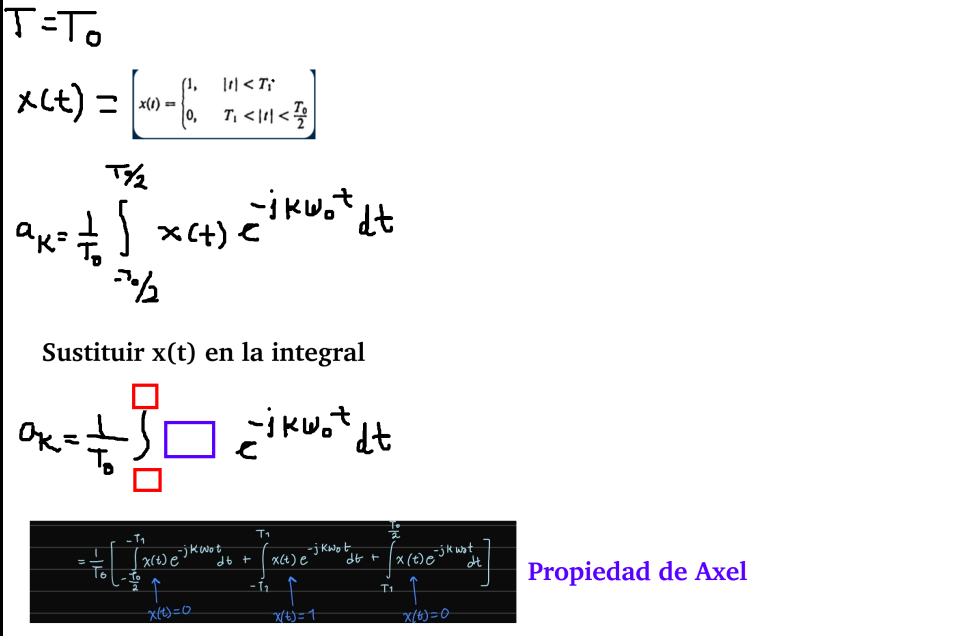

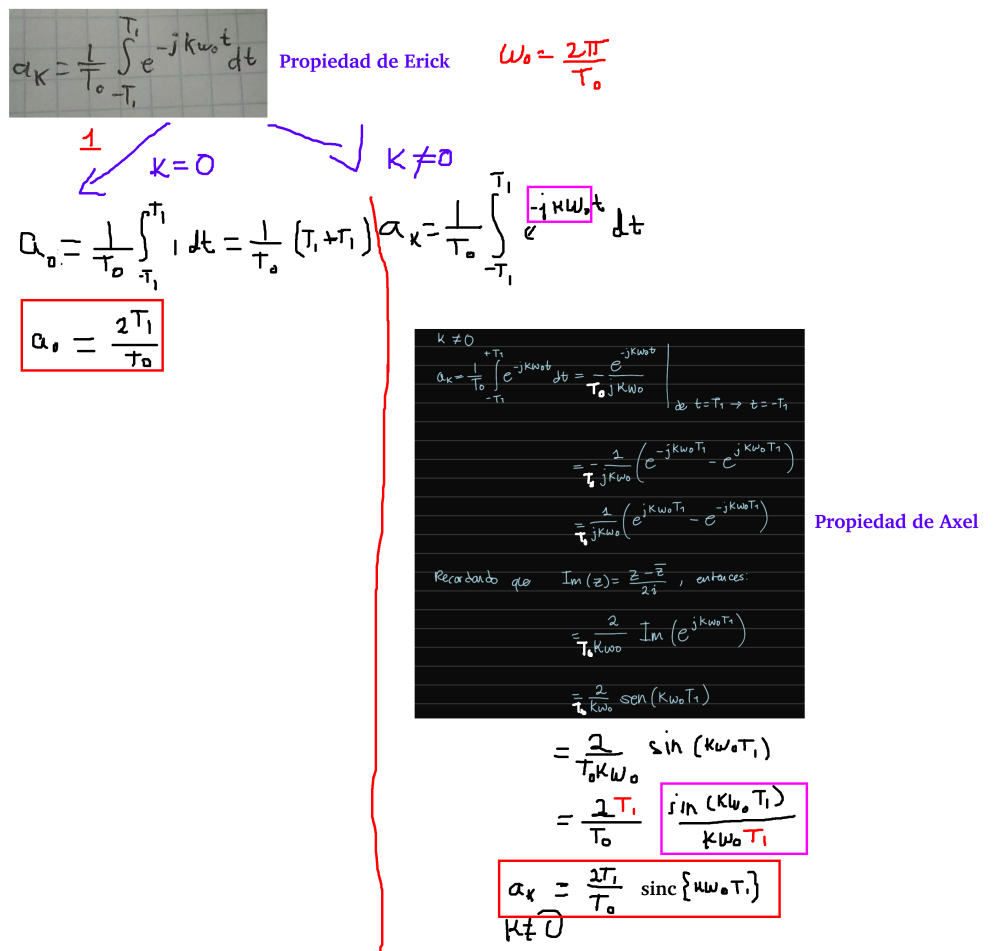

## Ploteo onda cuadrada

N=100;
k=-N:N;

A=8;
T0=2;
T1=T0/A;

w0=2*pi/T0;


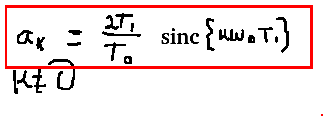

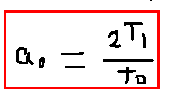

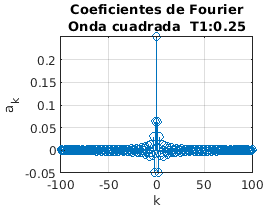

a_k=(2*T1/T0)*sinc(k*w0*T1);
a_0=2*T1/T0;

%La ecuación de a_k general no funciona
%Para k=0, por eso sustituimos un valor
%previamente calculado.
a_k(k==0)=a_0;

figure
stem(k,a_k)
xlabel("k")
ylabel("a_k")
grid on
title(["Coeficientes de Fourier";"Onda cuadrada  T1:"+T1])

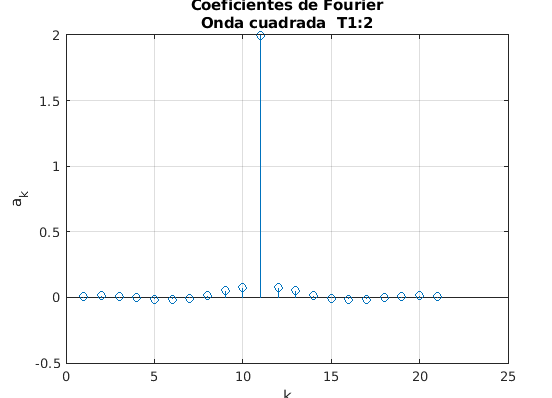 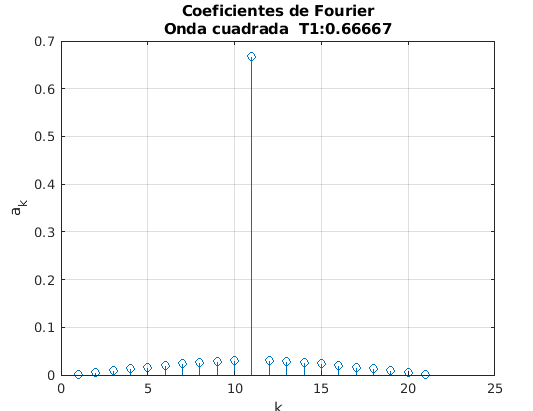

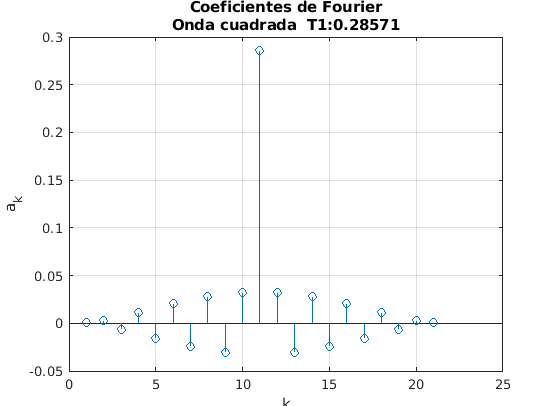

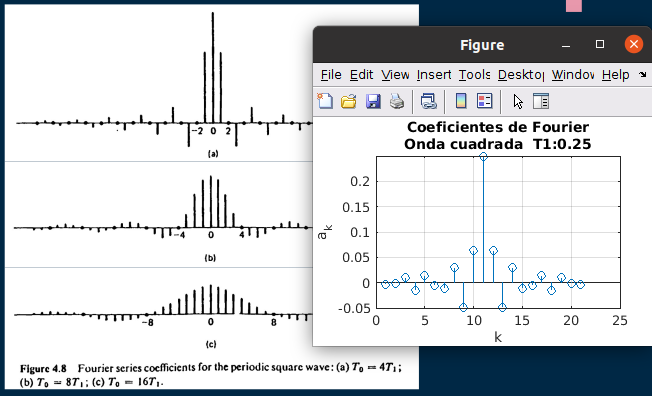

## Síntesis

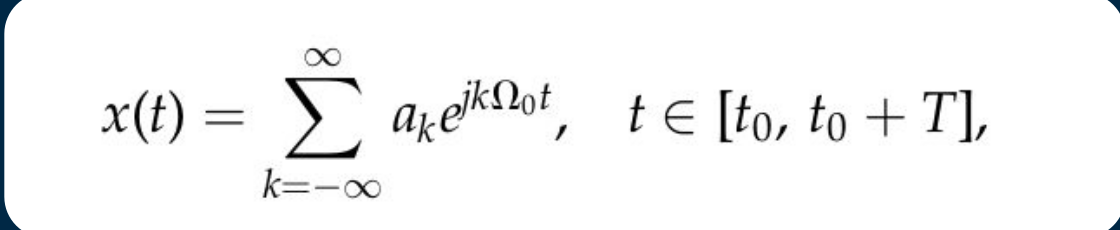

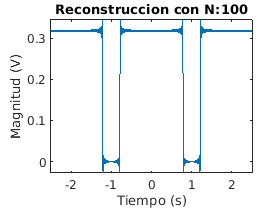

syms t
n=-3:3;
% %Numero de elementos
% numel()
% %Tamaño de la matriz en n X m
% size()
% %Tamaño más grande de la matriz 
% length()

x=sum(a_k.*exp(1i*k*w0*t));


figure
fplot(x,[-2.5 2.5])
xlabel("Tiempo (s)")
ylabel("Magnitud (V)")
title("Reconstruccion con N:"+N)